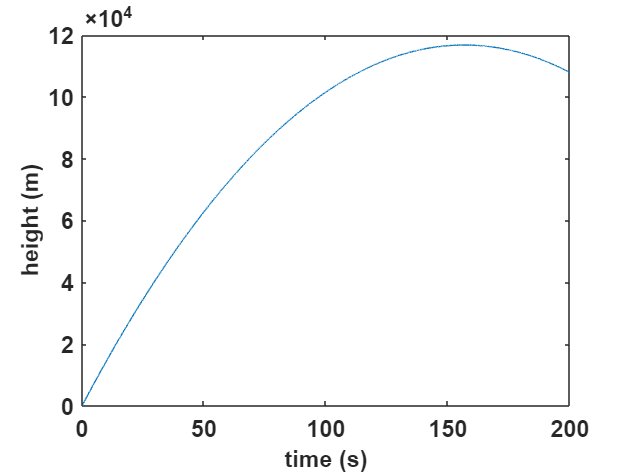

R = 6.37*10^6;
g0 = 9.81;


tspan=0:0.01:200;
y0 = [0, 1500];

[t,y]=ode45(@projectile,   tspan  ,   y0   );

x = y(:, 1);
v = y(:, 2);

plot(   t, x    );
set(gca, 'fontsize',14,'fontweight','bold');
ylabel('height (m)','fontsize',14,'fontweight','bold')
xlabel('time (s)','fontsize',14,'fontweight','bold')



[top,I]=max(x)

top =      1.167813090561475e+05

I =        15667

toptime=t(I)

toptime =      1.566600000000000e+02

function dy = projectile( t,y ) 

R = 6.37*10^6;
g0 = 9.81;

x = y(1);
v = y(2);

dy = zeros(2, 1);
dy(1) = v;
dy(2) = -g0 * R^2 /(R+x)^2;

end

